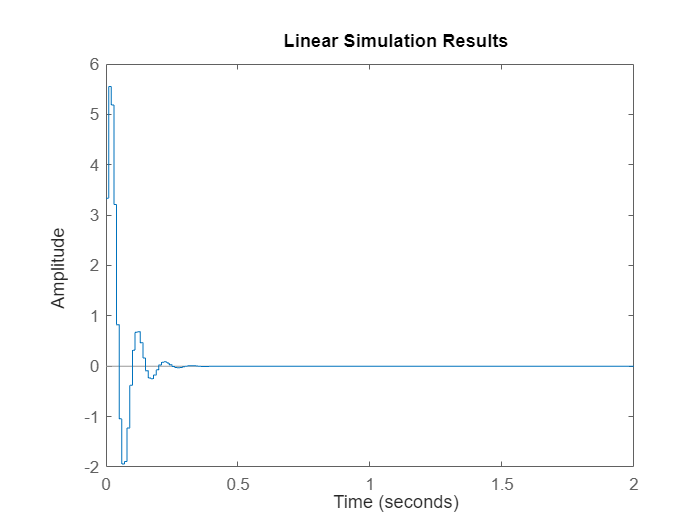

clc
clear all
close all
A = [4/3 -2/3; 1 0];
B = [1 0]';
C = [-2/3 1];

Q = C'*C + 0.001*eye(2,2);
R = 0.001;
x0= [10 10]';
x([1 2],1) = x0;

T=0.01;
model = ss(A,B,C,0,T);
% Risposta libera
time = 0:T:2;
lsim(model, zeros(length(time),1), time,x0)

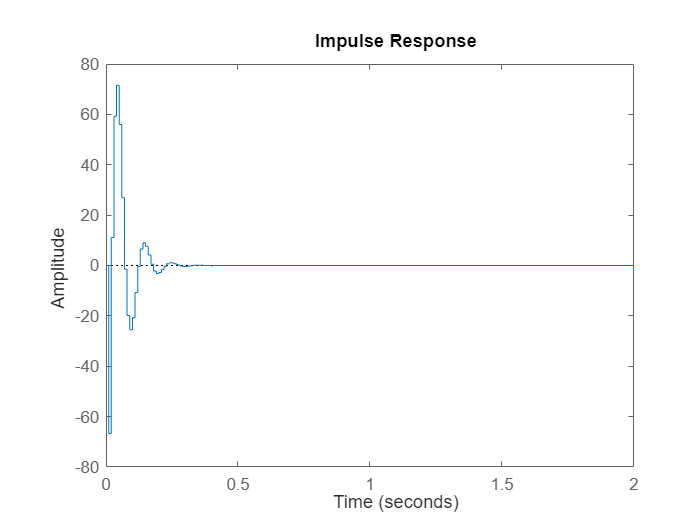

%Risposta all'impulso
impulse(model,time)

%% Stabillity - Plot - Cost of trajectory
N = 8;
tmax = 20;
[x,u, K] = LQR_funct_state_evolution(A, B, C, Q, R, N, x0, tmax);

%To check the stability, the matrix A+B*K must be considered:
eig(A+B*K(:,:,1))

ans =     0.8464
    0.0010


assert(all(abs(eig(A+B*K(:,:,1)))<1))

PLOT

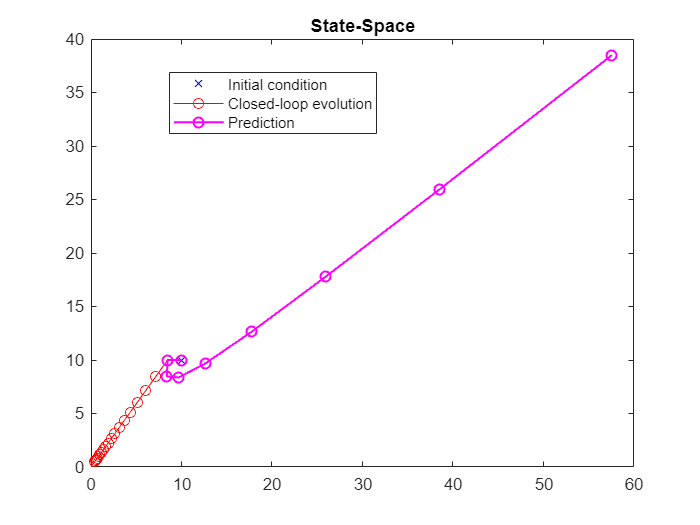

plot(x0(1), x0(2), 'bx')
hold on

plot(x(1,:), x(2,:), 'r-o')

% Calculating and plotting the prediction (from x0)
xpred([1 2],1) =x0;
for k=1:N
    xpred(:,k+1) = A*xpred(:,k) + B*(K(:,:,k)*xpred(:,k)); % fixed
end 
plot(xpred(1,:),xpred(2,:),'m-o','LineWidth',1.2);

legend('Initial condition','Closed-loop evolution','Prediction');
title('State-Space');
hold off

legend("Position", [0.24074,0.74413,0.29821,0.11905])


% Cost of this trajectory
V = sum(sum((x'*Q*x + x'*K(:,:,N+1)'*R*K(:,:,N+1)*x),1),2);



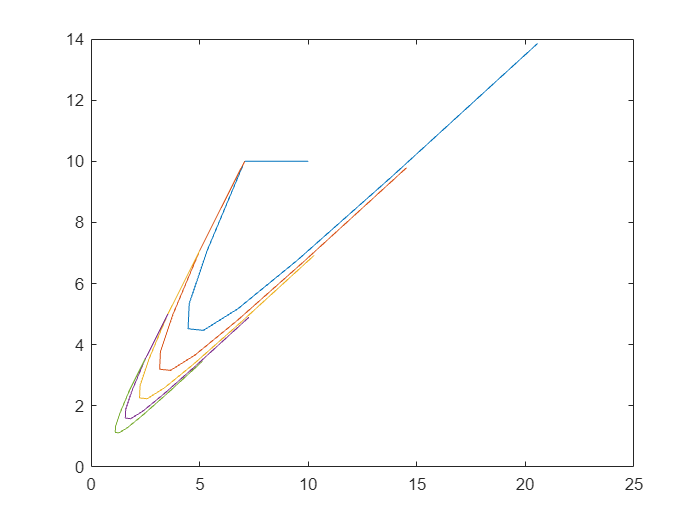


%% Trajectories with different time horizon
x0n = x0;
N = 10;
for k = 1:5
    [x,u, K] = LQR_funct_traj_prediction(A, B, C, Q, R, N, x0n);
    plot(x(1,:), x(2,:))
    hold on
    x0n = x(:,2);
end
hold off